per = 10

optrank_less = 5

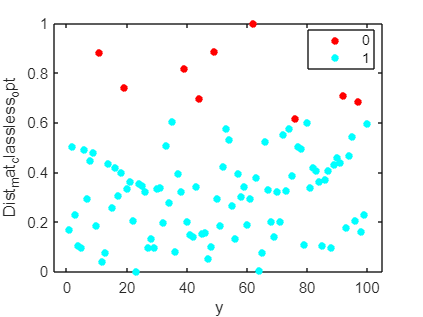

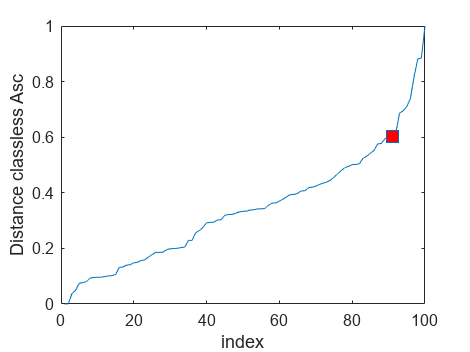

optrank_more = 5

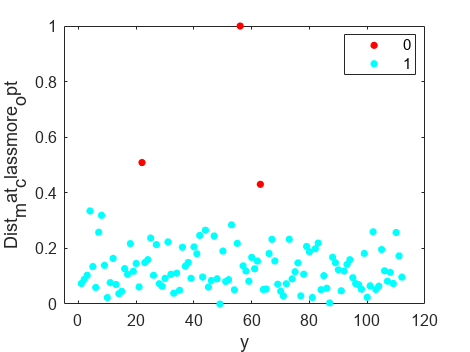

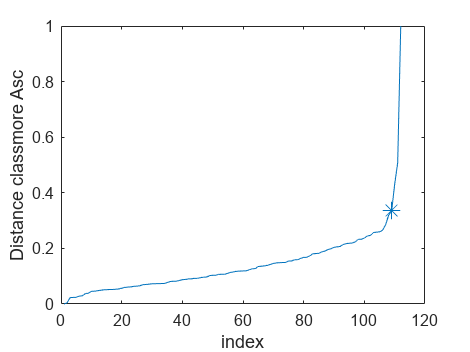

per = 10

optrank_less = 20

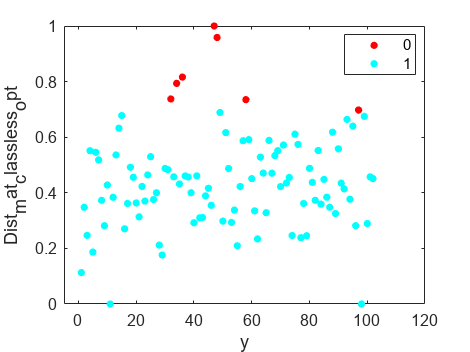

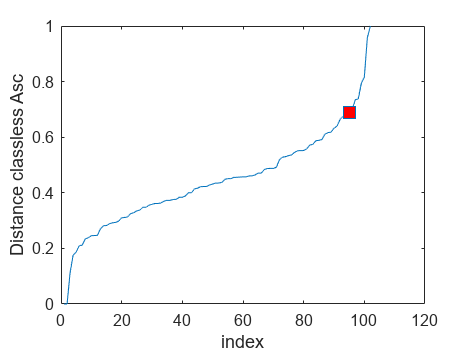

optrank_more = 1

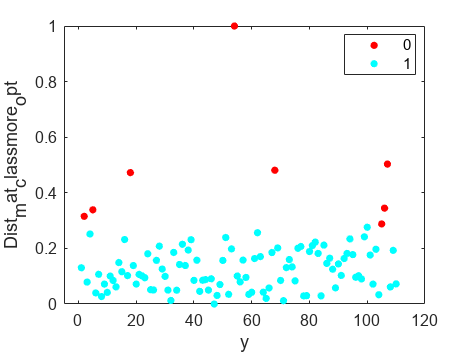

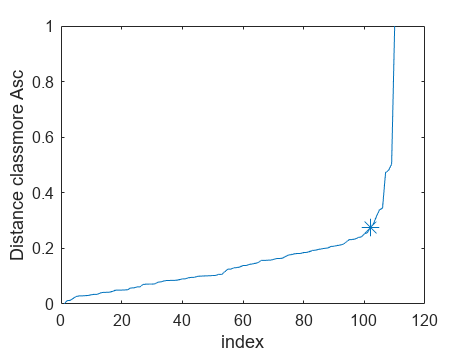

per = 10

optrank_less = 20

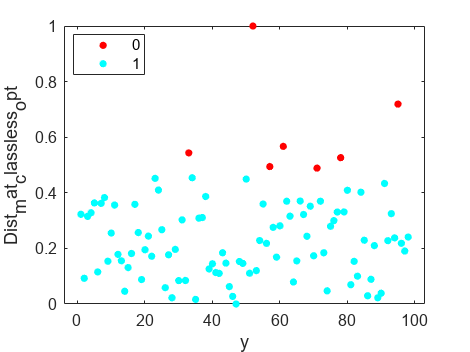

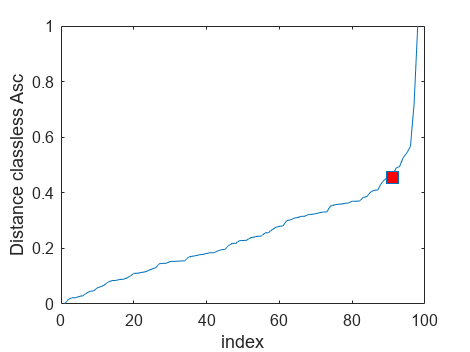

optrank_more = 1

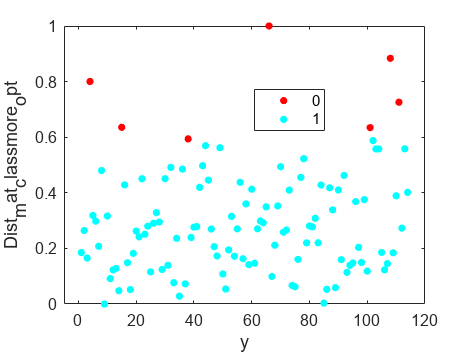

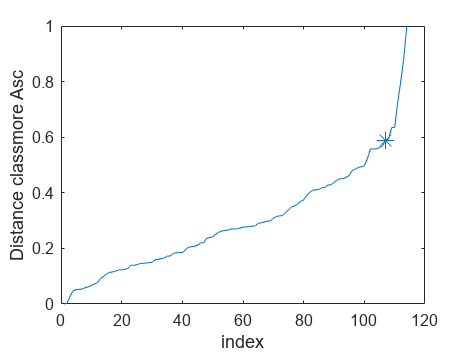

per = 10

optrank_less = 15

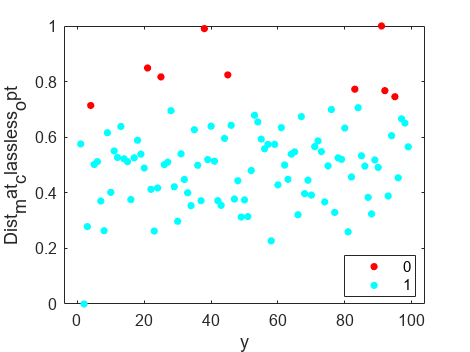

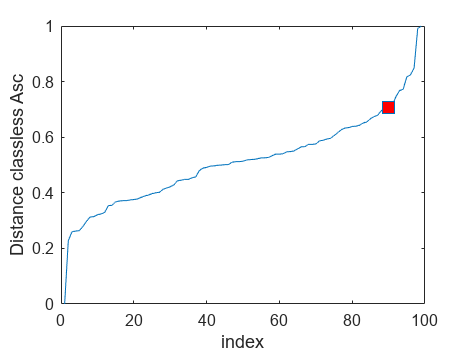

optrank_more = 5

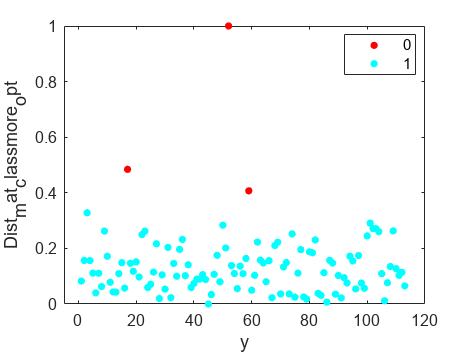

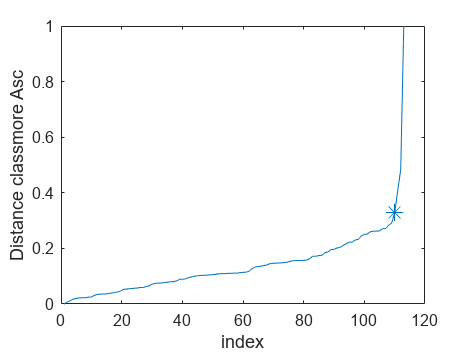

per = 10

optrank_less = 25

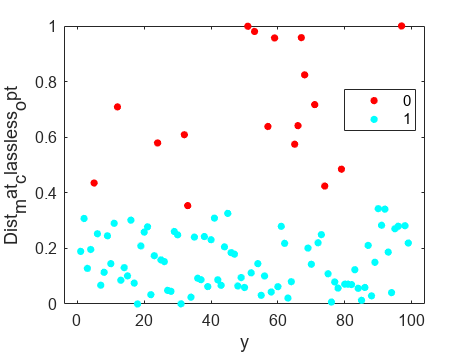

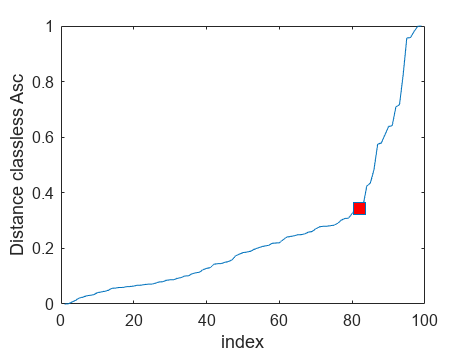

optrank_more = 1

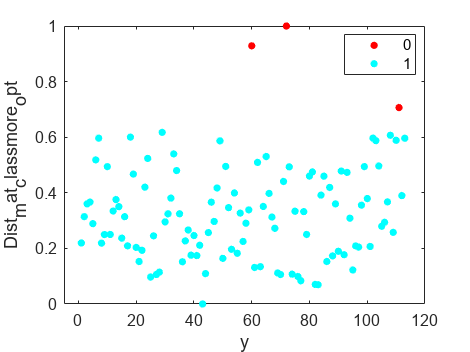

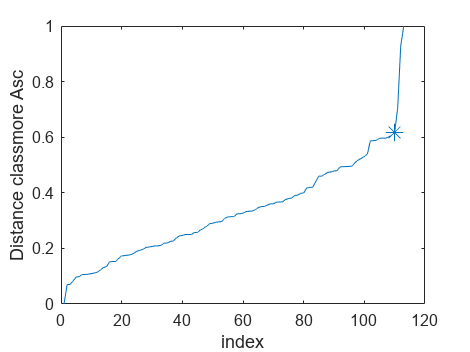

per = 10

optrank_less = 10

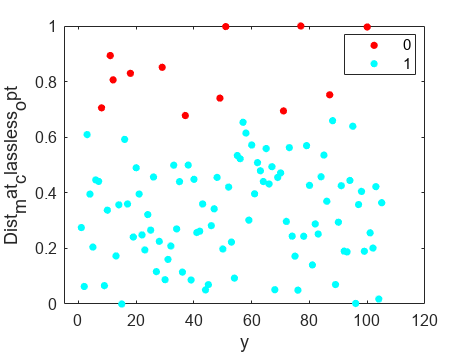

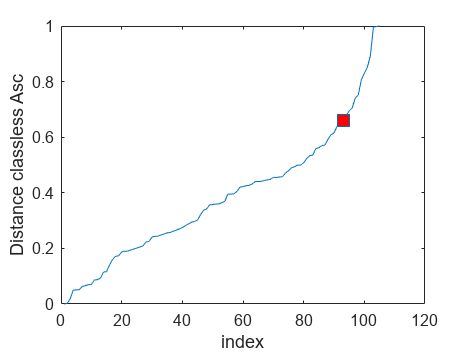

optrank_more = 5

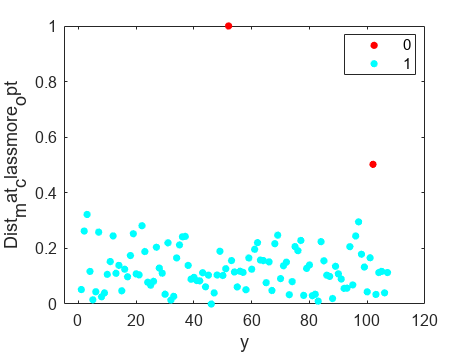

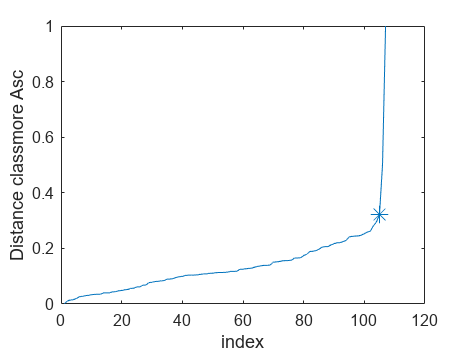

per = 10

optrank_less = 20

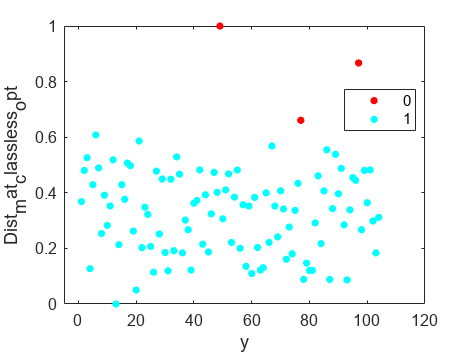

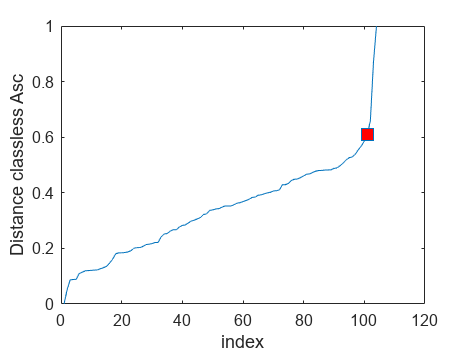

optrank_more = 5

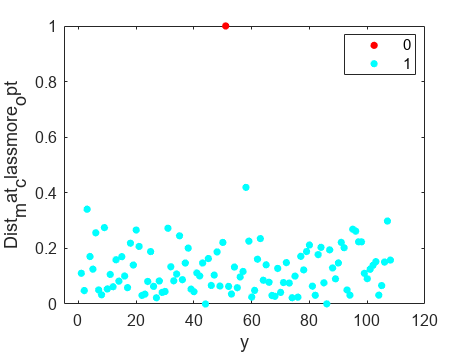

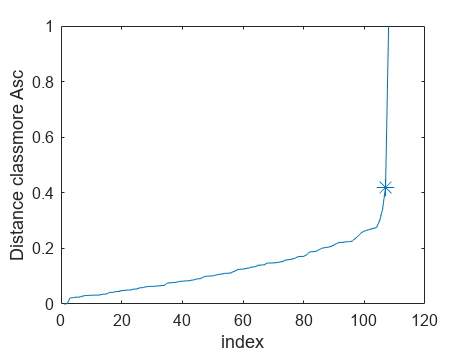

per = 10

optrank_less = 5

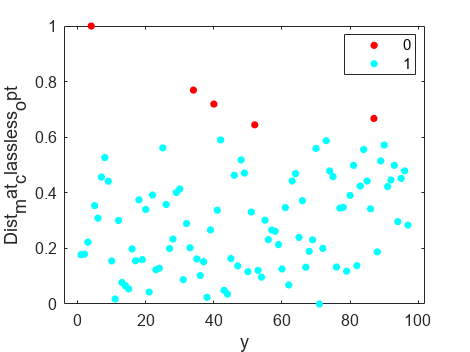

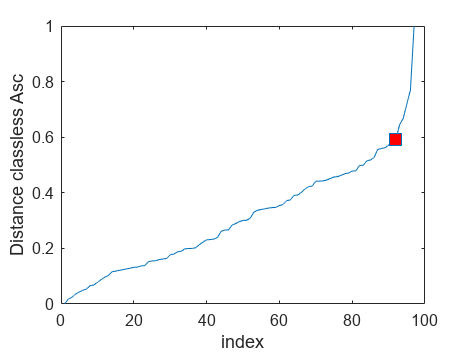

optrank_more = 1

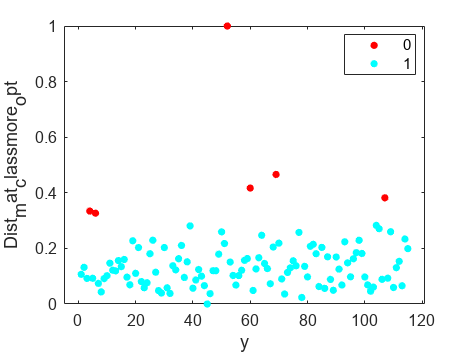

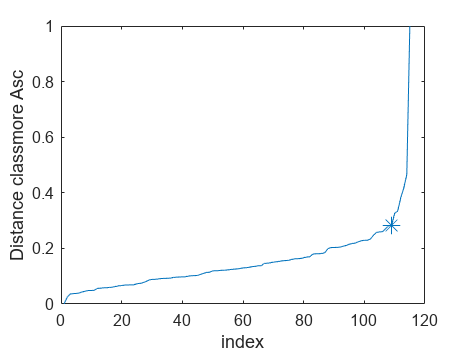

per = 10

optrank_less = 10

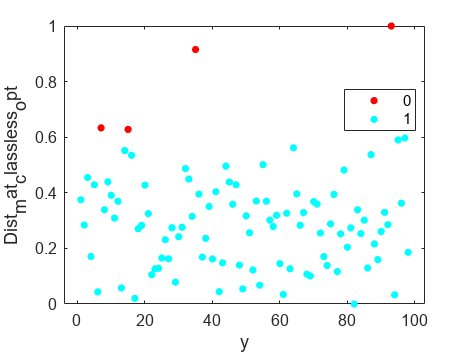

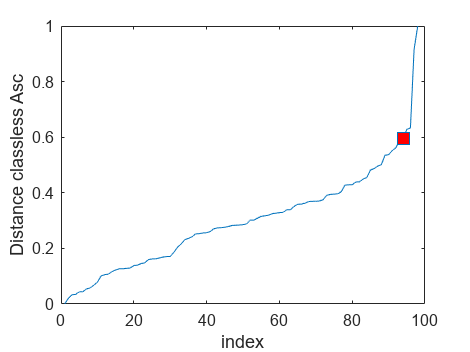

optrank_more = 5

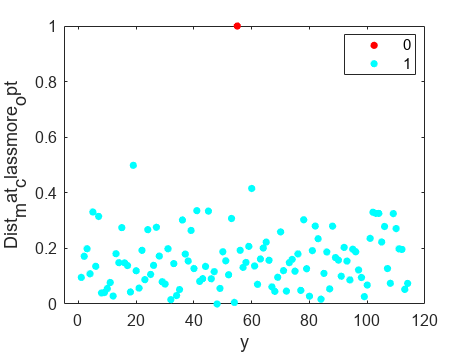

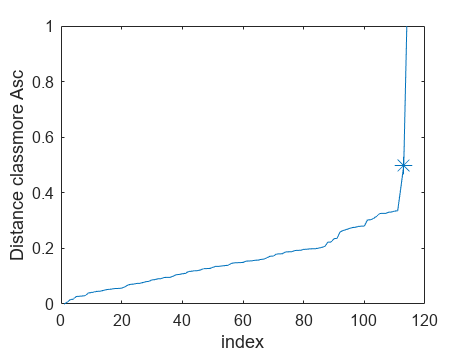

per = 10

optrank_less = 5

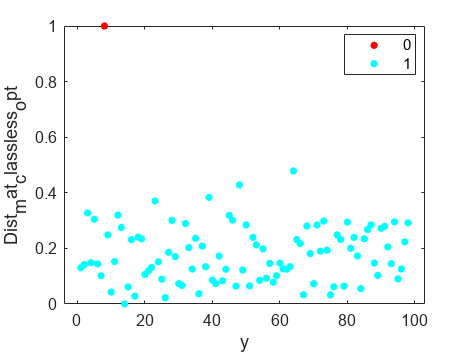

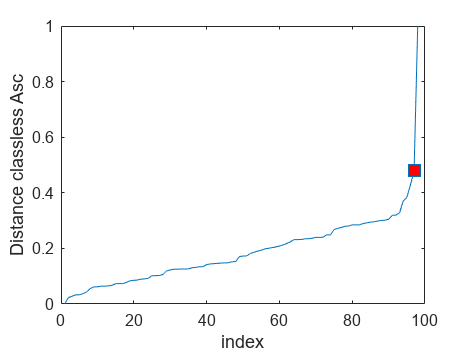

optrank_more = 10

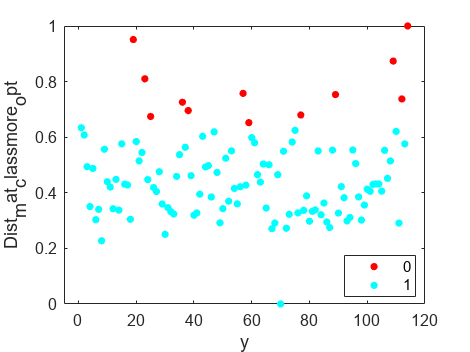

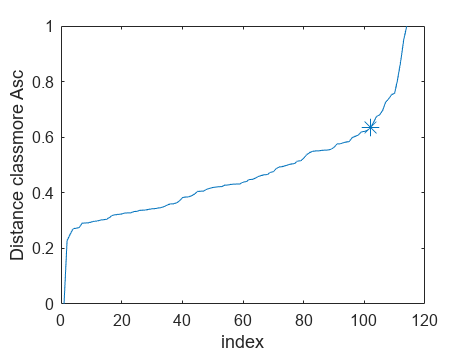

for j = [1,2,3,4,5,6,7,8,9,10]
    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\heart\split1\per0\heart_en_misclass_per_0.csv",",",1);
    per =10%[20,10,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\heart\
        mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)


        my_file = strcat('heart_en_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        %classless=File(File(:,14)==0,1:13);
        classless=File(File(:,28)==0,1:27);
        T_classless=classless.';
       

        %classmore=File(File(:,14)==1,1:13);
        classmore=File(File(:,28)==1,1:27);
        T_classmore=classmore.';


        folder_l1=strcat('ACE_dist_misc_optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,5,10,15,20,25];

        error_classless = nan(size(ranks));
        numclassless=length(T_classless);
        Dist_mat_classless_array_asc=nan(length(ranks),numclassless);
        threshold_rank_less=nan(size(ranks));
        elbow_indx_rank_less=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\heart\

            T_classless_temp=T_classless;
            Dist_mat_classless=[];


            BF_classless=l1pca_BF(T_classless,i,1,10,10,'');
            for k = 1 : numclassless
                A=T_classless(:,k);
                Dist_mat_classless(k)=norm((A-(BF_classless*BF_classless.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_classless,[],"all");
            max_val=max(Dist_mat_classless,[],"all");
            Dist_mat_classless= Dist_mat_classless-min_val;%]/[max_val-min_val]
            Dist_mat_classless=Dist_mat_classless /(max_val-min_val);


            Dist_mat_classless_array_asc(i,:)=Dist_mat_classless;
            [Dist_mat_classless_asc,Indx_less]=sort(Dist_mat_classless,"ascend");


            [elbow_less_err_angle,elbow_indx_less]=knee_pt_angle((Dist_mat_classless_asc));

            error_classless(i)=elbow_less_err_angle;
            threshold_rank_less(i)=Dist_mat_classless_asc(elbow_indx_less);
            elbow_indx_rank_less(i)=elbow_indx_less;

        end

        [~,optrank_less]= max(error_classless)

        Dist_mat_classless_opt=Dist_mat_classless_array_asc(optrank_less,:);
        threshold_dist_less= threshold_rank_less(optrank_less);
        elbow_indx_less_opt=elbow_indx_rank_less(optrank_less);

        ind_O_less=find(Dist_mat_classless_opt>threshold_dist_less);
        ind_I_less=find(Dist_mat_classless_opt<=threshold_dist_less);


        cluster_less=zeros(size(Dist_mat_classless_opt));
        cluster_less(ind_I_less)=1;
        figure
        y= 1:1:length(classless);
        numGroups = length(unique(cluster_less));
        gscatter(y,Dist_mat_classless_opt,cluster_less,hsv(numGroups))

        figure
        plot(sort(Dist_mat_classless_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_less_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel("Distance classless Asc")
        ind_O_less;


        T_classless_temp(:,ind_O_less)=[];
        length(T_classless_temp);
      

        Final_classless=T_classless_temp';
        cless=0*ones(size(Final_classless,1),1);
        Final_classless=[Final_classless cless];


        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_classmore = nan(size(ranks));
        numclassmore=length(T_classmore);
        Dist_mat_classmore_array_asc=nan(length(ranks),numclassmore);
        threshold_rank_more=nan(size(ranks));
        elbow_indx_rank_more=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\heart\

            T_classmore_temp=T_classmore;
            Dist_mat_classmore=[];


            BF_classmore=l1pca_BF(T_classmore,i,1,10,10,'');
            for k = 1 : numclassmore
                A=T_classmore(:,k);
                Dist_mat_classmore(k)=norm((A-(BF_classmore*BF_classmore.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_classmore,[],"all");
            max_val=max(Dist_mat_classmore,[],"all");
            Dist_mat_classmore= Dist_mat_classmore-min_val;%]/[max_val-min_val]
            Dist_mat_classmore=Dist_mat_classmore /(max_val-min_val);


            Dist_mat_classmore_array_asc(i,:)=Dist_mat_classmore;
            [Dist_mat_classmore_asc,Indx_more]=sort(Dist_mat_classmore,"ascend");


            [elbow_more_err_angle,elbow_indx_more]=knee_pt_angle(Dist_mat_classmore_asc);

            error_classmore(i)=elbow_more_err_angle;
            threshold_rank_more(i)=Dist_mat_classmore_asc(elbow_indx_more);
            elbow_indx_rank_more(i)=elbow_indx_more;

        end

        [~,optrank_more]= max(error_classmore)

        Dist_mat_classmore_opt=Dist_mat_classmore_array_asc(optrank_more,:);
        threshold_dist_more= threshold_rank_more(optrank_more);
        elbow_indx_more_opt=elbow_indx_rank_more(optrank_more);

        ind_O_more=find(Dist_mat_classmore_opt>threshold_dist_more);
        ind_I_more=find(Dist_mat_classmore_opt<=threshold_dist_more);


        cluster_more=zeros(size(Dist_mat_classmore_opt));
        cluster_more(ind_I_more)=1;
        figure
        y= 1:1:length(classmore);
        numGroups = length(unique(cluster_more));
        gscatter(y,Dist_mat_classmore_opt,cluster_more,hsv(numGroups))

        figure
        plot(sort(Dist_mat_classmore_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_more_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel("Distance classmore Asc")
        ind_O_more;


        T_classmore_temp(:,ind_O_more)=[];
        length(T_classmore_temp);

        Final_classmore=T_classmore_temp';

        cmore=1*ones(size(Final_classmore,1),1);
        Final_classmore=[Final_classmore cmore];


        cd C:\Users\shukl\Documents\GitHub\heart\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_classless.',Final_classmore.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:28)=  M.colheaders;
        filel1pca=strcat('heart_en_misclass_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca);
    end
end